% CALC'S FOR LATER
RoundXpts = round(abs(ypts)); %switch x & y
RoundYpts = round(abs(xpts));


clear PTSdfof % pulling fluoresence data from just teh points picked in threshPassAnalysis script
for i = 1:length(xpts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:);
end
display('size of PTSdfof is: ')
size(PTSdfof)


% x axis
% plot each graph for dfof traces for each point as subplots on the same main plot
frameNum = 1:size(onsetDf,3); % making the x axis frame number - 3rd dimension (frames) of onsetDf 


% DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% need to make vectors with duration values
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    % note: stim details contains info (incl. contrast values) for every 
    % possible condition. It is NOT ordered by trial.
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

% note: trial cond is a list of indicies for rown in stimdetails - with this you can index what stim conditions (duration, contrast etc) were displayed each trial
% These indicies *are* ordered by trial
% so now, by using trialCond to index into d, we can get a list of stimulus in the order that they were presented:

durOrderedByTrial = dur(trialCond); % save in new vector that is a list 
% of trial conditions ordered by trial

% gets a list of the duration value options, so we know how many durations to loop over
uniqueDurations = unique(dur); 

subtractLast3UniqueDurations = uniqueDurations(:,1:length(uniqueDurations)-3);


% DURATION


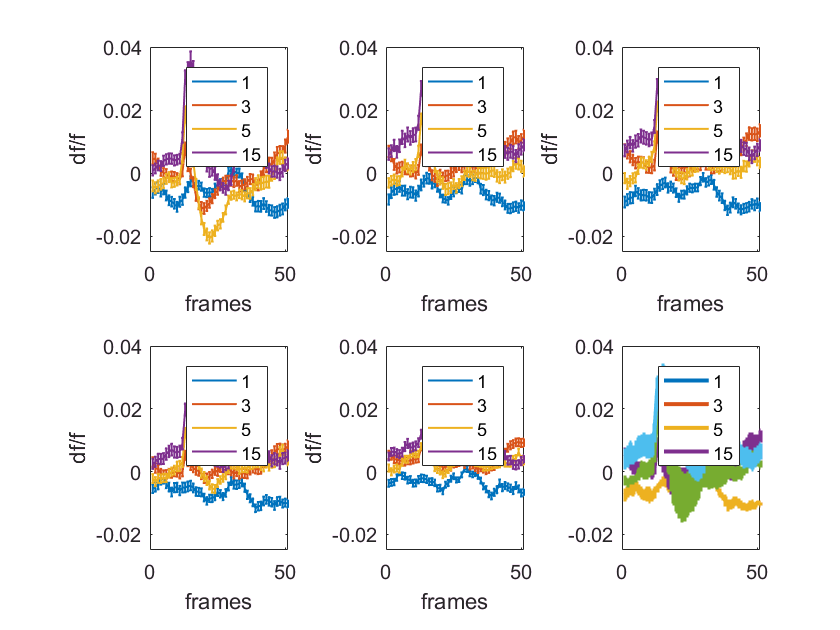

% DFOF VS FRAMES, TRACE = DURATION, SUBPLOT = POINT
% now we're going to plot one figure, and each subplot is for one point with
% several traces - one for each duration. Each trace is dfofof for that point, over over frames, for one duration

figure % only making 1 figure
% suptitle(sprintf('EE81LT: df/f vs frames for each contrast at each point'))   
clear i
for i = 1:length(xpts) % for each point
    subplot(2,3,i) % give each point it's own subplot
    % on each subplot plot the mean dfof across trials, vs frames, for each duration
  
    for d = 1:length(subtractLast3UniqueDurations) 
        
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == subtractLast3UniqueDurations(d);
 
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % creating a 
        % 1 by # frames variable that has dfof of one point averaged across trials
        % at the d-th contrast, for all frames
        
        %STDEV
        err = std(PTSdfof(i,:,dthTrials),[],3)/sqrt(length(dthTrials)); % across all trials = 3rd dim
     
        errorbar(frameNum,meanOverTrialsPTSdfof,err, 'linewidth',1)
        % plot(frameNum,meanOverTrialsPTSdfof, 'linewidth',1)
        ylim([-0.025 0.04]) 
        xlim([0 51])
        ylabel('df/f')
        xlabel('frames')
        hold on
        
    end 
    legend('1','3','5','15')
    
    % now  I want the 6th subplot to be the
    % mean trace for each point across all durations 
    % update: subtract the control point from the averages
    hold on
   
    clear d
    for d = 1:length(subtractLast3UniqueDurations)
     
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == subtractLast3UniqueDurations(d);
   
        % for each dth duration, subtracting the 5th point 
        % & taking mean across trials 
        % returns 4 rows (points) bx 50 frames/columns
        clear meanOverTrialsPTSdfofMinusControl
        clear meanOverPointsMeanOverTrialsPTSdfofMinusControl
        clear err
        
        meanOverTrialsPTSdfofMinusControl = mean(PTSdfof(1:size(PTSdfof,1)-1,:,dthTrials),3);
        % now take mean across points, leaving only the dth df/f vs frames
        meanOverPointsMeanOverTrialsPTSdfofMinusControl = mean(meanOverTrialsPTSdfofMinusControl,1);
       
        %%err = std(PTSdfof(i,:,dthTrials),[],3)/sqrt(length(dthTrials)); % across all trials = 3rd dim
        % std err over visual areas [update had to do frames die to size mismatch]
        err = std(meanOverTrialsPTSdfofMinusControl,1);
        
        %%errorbar(frameNum,meanOverTrialsPTSdfof,err, 'linewidth',1)
        
        x_axis = 1:size(meanOverPointsMeanOverTrialsPTSdfofMinusControl,2);
        subplot(2,3,6)
        errorbar(x_axis,meanOverPointsMeanOverTrialsPTSdfofMinusControl,err,'linewidth',2)
        %plot(x_axis,meanOverPointsMeanOverTrialsPTSdfofMinusControl,'linewidth',2)
        xlim([0 51])
        ylim([-0.025 0.04])
        hold on
    end
    legend('1','3','5','15')
     
%     for j = 1:length(xpts)-1 % subtract the control point from the averages
%         subplot(2,3,6)
%         plot(mean(squeeze(PTSdfof(j,:,:)),2),'linewidth',2) % here's plotting the mean over trials (dimension 2 in PTSdfof)
%         ylim([-0.01 0.04]) 
%         xlim([0 51])
%         ylabel('df/f')
%         xlabel('frames')
%         hold on
%         end
%         legend('V1','HVA_2','HVA_3','HVA4')
end 

% DRF -  Duration Response Function over frames 14-16

% want to plot response vs duration for each duration and in each visual area

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 14:16;
durationValues = [1 3 5 15];

figure % make figure outside i loop & all others b/c each point is a subplot w/DRF for that point
suptitle('Duration Response Function for each Point') 
for i = 1:length(xpts) % for each point
    
     clear sq5FramesOverTrialsPTSdfof
     clear meanOverFramesSq5FramesOverTrialsPTSdfof
     clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
     clear durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
     clear durStdErr
    
    for d = 1:length(subtractLast3UniqueDurations)
       
        % collecting trials at the d-th duration
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == subtractLast3UniqueDurations(d);
        
        % DRF VALUES for each duration, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,dthTrials));
        
        % take the mean over frames
        % returns 1 x # trials
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each c-th DRF value for this point
        % creates 1 x # durations
        durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr for each DRF point calulated above
        % (one err value for each duration)
        % that means I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
        durStdErr(1,d) = stdErr; % store stdErr for each duration in a new 
        % vector where each err is in the first row and c-th column
        
    end 
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1:length(subtractLast3UniqueDurations)];
    errorbar(x_axis,durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,durStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue') 
    ylim([-0.01 0.05]) 
    ylabel('df/f')
    xlim([0, 5])
    %xticklabels({'0.016','0.05','0.083','0.25','0.5','1','1667'})
    xlabel('seconds')
    
    %% ylabel('df/f')
    %% xlabel('contrast')
    
end 

%savefig('G6H277RT_020421_DRF')